# Mohammadreza Arani

## COnvex Optimization

## 810100511

% Q6:

clear; clc; close all;
% Load Data:
run('plannning_data.m');

## First Case:


cvx_begin
variable q(n); % quantity of products    
variable r(m); % amount of raw material
    
   % Constraints:   
    S = min(q*ones(1,K),D); % finding minimum of q,D (same as d)
    
    q >= 0;
    r >= 0;  
    r >= A*q;
    
% vector pi is given as init points:    
    maximize(p'*S*pi - c'*r) % Objective function :pT.min(q,d)-CTr
    
cvx_end % having given probabilities as (pi)

 
Calling SDPT3 4.0: 1525 variables, 760 equality constraints
------------------------------------------------------------

 num. of constraints = 760
 dim. of linear var  = 1525
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.8e+02|2.7e+02|1.9e+07| 3.573278e+04  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.984|0.958|6.2e+00|1.2e+01|8.5e+05| 3.565719e+04  3.747622e+01| 0:0:00| spchol  1  1 
 2|1.000|0.722|3.3e-06|3.4e+00|2.7e+05| 3.407038e+04  6.463390e+01| 0:0:00| spchol  1  1 
 3|1.000|0.506|7.5e-07|1.7e+00|2.1e+05| 4.137193e+04  5.420024e+01| 0:0:00| spchol  1  1 
 4|1.000|0.569|4.2e-06|7.9e-01|1.3e+05| 3.767296e+

rI = r % see the amount of materials

rI =    45.5203
   65.8287
   44.6489
   76.6555
   71.9572
   77.8437
   59.2585
   61.8943
   83.2460
   73.0732


fprintf('<CVX_optimal Value = Profit =  "%f"\n',cvx_optval)

<CVX_optimal Value = Profit =  "114.331327"


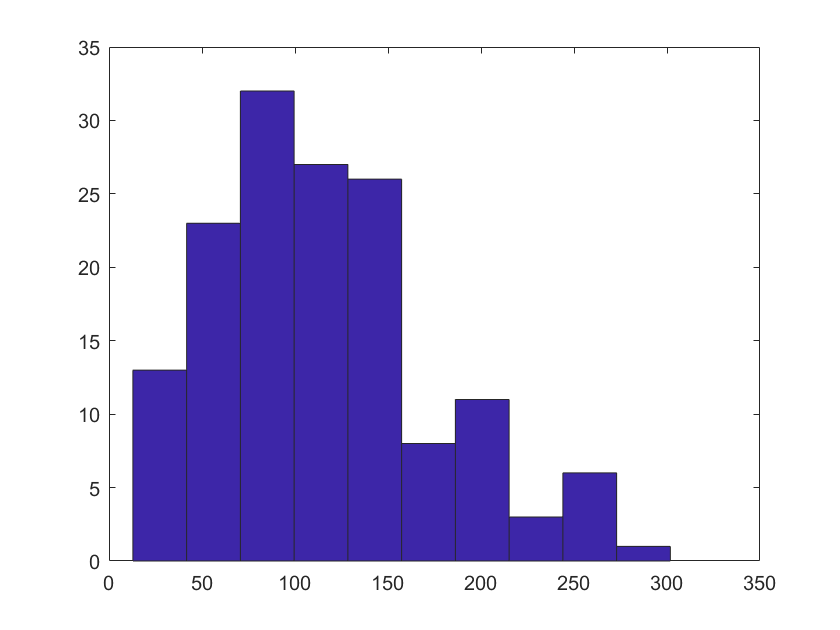

% Profit from this kind of viewing at problem:
profit1 = p'*S - c'*r; % keeping
nbins = 10;
hist(profit1, nbins)%%

Second Problem:


cvx_begin
variable q(n, K); % quantity of products    
variable r(m); % amount of raw material
    
   % Constraints:   
    S = min(q, D); % finding minimum of q,D (same as d)
    
    q >= 0;
    r >= 0;  
    %r >= A*q;
    r*ones(1,K) >= A*q;
    
% vector pi is given as init points:    
    maximize(p'*S*pi - c'*r) % Objective function :pT.min(q,d)-CTr
    
cvx_end % having given probabilities as (pi)

 
Calling SDPT3 4.0: 3760 variables, 1510 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 1510
 dim. of linear var  = 3760
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.5e+04|6.2e+01|1.6e+07|-7.258741e+04  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.146|1.000|1.3e+04|2.6e-01|2.0e+07|-5.998374e+04 -1.185476e+04| 0:0:00| spchol  1  1 
 2|0.976|1.000|3.1e+02|7.8e-02|4.9e+05|-1.466577e+03 -1.184934e+04| 0:0:00| spchol  1  1 
 3|0.942|1.000|1.8e+01|7.8e-03|3.7e+04|-1.467188e+02 -1.003753e+04| 0:0:00|

rI = r % see the amount of materials

rI =    65.6924
   59.6062
   55.1515
   70.7618
   69.7342
   68.3545
   55.3436
   57.3714
   63.7671
   66.1721


fprintf('<CVX_optimal Value = Profit =  "%f"\n',cvx_optval)

<CVX_optimal Value = Profit =  "133.039255"


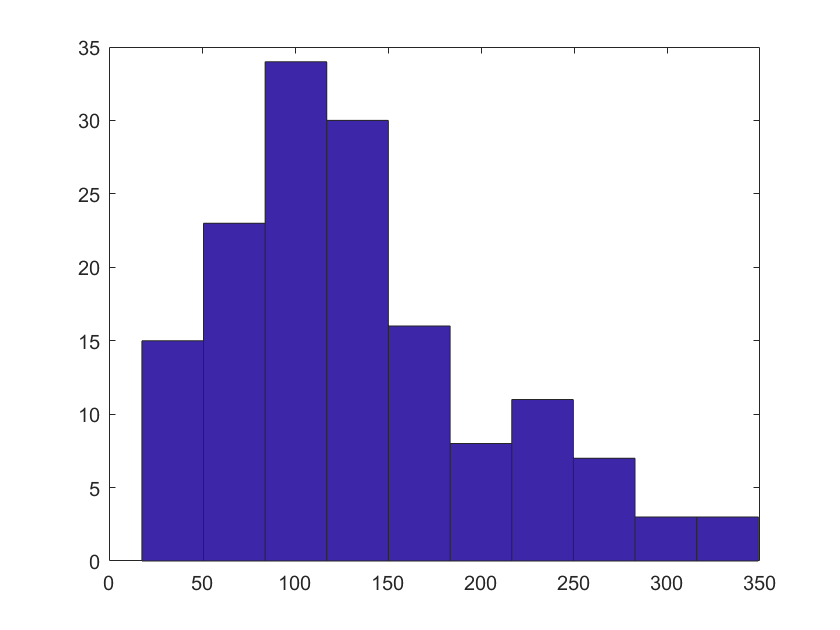

% Profit from this kind of viewing at problem:
profit2 = p'*S - c'*r; % keeping
nbins = 10;
hist(profit2, nbins)

r = rI; % Having rI from previous step
cvx_begin
    variable q(n, K); % quantity of products paired with demands    
    r*ones(1,K) >= A*q; q >= 0; S = min(q, D);    
    maximize(p'*S*pi - c'*r)% Same Objective as ever!
cvx_end

 
Calling SDPT3 4.0: 3750 variables, 1500 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 1500
 dim. of linear var  = 3750
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.4e+04|6.1e+01|5.6e+08| 5.732385e+06  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.961|0.887|5.6e+02|6.8e+00|3.2e+07| 3.382605e+05 -2.556678e+05| 0:0:00| spchol  1  1 
 2|0.942|0.790|3.2e+01|1.4e+00|6.0e+06| 2.174498e+05 -3.145191e+05| 0:0:00| spchol  1  1 
 3|1.000|1.000|5.7e-05|6.7e-04|3.2e+05| 1.950165e+05 -1.187988e+05| 0:0:00|

fprintf('<CVX_optimal Value = Profit =  "%f"\n',cvx_optval)

<CVX_optimal Value = Profit =  "133.039255"


% Profit from this kind of viewing at problem:
profit2_rI = p'*S - c'*r; % keeping
nbins = 10;
hist(profit2_rI, nbins)

## Final Point of View:

cvx_begin
variable r(m, K); % amount of raw material for each demands
variable q(n, K); % quantity of products paired with demands    
  
   S = min(q, D); r >= A*q; r >= 0;  q >= 0;
    
    maximize((p'*S - c'*r)*pi)
cvx_end

 
Calling SDPT3 4.0: 5250 variables, 2250 equality constraints
------------------------------------------------------------

 num. of constraints = 2250
 dim. of linear var  = 5250
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.1e+03|6.8e+02|2.2e+08| 2.811282e+02  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.964|0.946|2.9e+02|3.8e+01|1.2e+07| 6.393142e+04 -2.087654e+02| 0:0:00| spchol  1  1 
 2|1.000|0.814|4.5e-05|7.2e+00|2.6e+06| 7.314090e+04 -1.260577e+02| 0:0:00| spchol  1  1 
 3|1.000|1.000|1.9e-05|1.2e-01|9.6e+04| 5.559950e+04 -9.626541e+01| 0:0:00| spchol  1  1 
 4|0.980|1.000|5.7e-07|6.2e-02|5.8e+03| 1.173726

fprintf('<CVX_optimal Value = Profit =  "%f"\n',cvx_optval)

<CVX_optimal Value = Profit =  "161.427376"


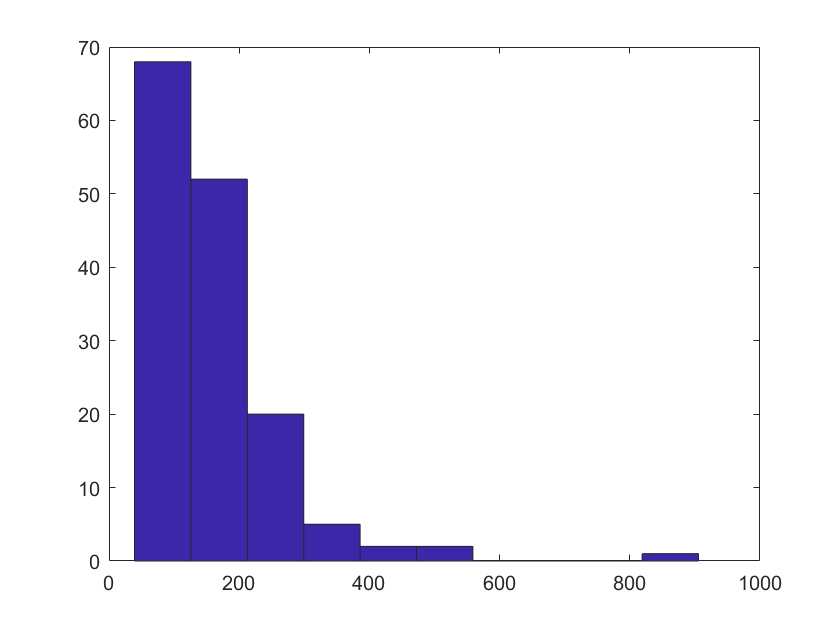

% Profit from this kind of viewing at problem:
profit3 = p'*S - c'*r; % keeping
nbins = 10;
hist(profit3, nbins)